clear all
clf

% 초기화
mapSize = 10; % 맵의 크기 (10m x 10m)
numLandmarks = 10; % 랜드마크의 수
landmarks = mapSize * rand(2, numLandmarks); % 랜드마크의 위치를 무작위로 초기화

landmarks(1:2,1) = [0;0];
landmarks(1:2,2) = [5;0];
landmarks(1:2,3) = [10;0];
landmarks(1:2,4) = [10;5];
landmarks(1:2,5) = [10;10];
landmarks(1:2,6) = [5;10];
landmarks(1:2,7) = [0;10];
landmarks(1:2,8) = [0;5];
landmarks(1:2,9) = [7;7];
landmarks(1:2,10) = [3;3];

robotPose = [5; 1; 0]; % 로봇의 초기 위치 (맵 중앙) 및 방향 (0 라디안)


% 모션 모델 파라미터
velocity = 0.7; % 로봇의 속도 (m/s)
yawRate = 0.15; % 로봇의 요율 (rad/s)

% 시뮬레이션 파라미터
detection_range = 4.0;
simulationTime = 60; % 시뮬레이션 시간 (초)
dt = 1; % 시간 간격 (초)
sim_pause = 0.1;

% EKF SLAM 초기화
slamState = [robotPose; zeros(numLandmarks*2, 1)]; % 로봇 상태 및 랜드마크 위치
landmarkInit = zeros(1,numLandmarks);
landmarkKnown = zeros(1,numLandmarks);
slamCovariance = blkdiag(zeros(3,3), 100 * eye(2*numLandmarks));
motionNoise = 0.001 * eye(3 + 2*numLandmarks); % 모션 노이즈
observationNoise = [0.5, 0;
                    0, 10*pi/180.0]; % 관측 노이즈
sim_observationNoise = [0.2, 0;
                        0, 3*pi/180.0];

% 이미 위치 아는 랜드마크
% idx = 2;
% slamCovariance(3 + idx*2-1:3 + idx*2, 3 + idx*2-1:3 + idx*2) = eye(2)*0.0;

figure;



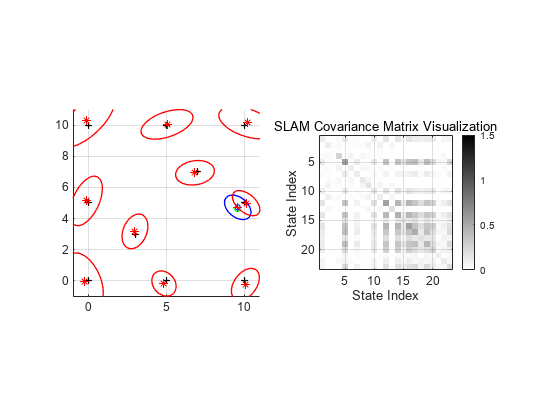


% 시뮬레이션 루프
for t = 0:dt:simulationTime
    cla; % 현재 축의 내용을 지웁니다.
    clf;
    % 모션 업데이트 sim
    robotPose = motionUpdate(robotPose, velocity, yawRate, dt);

    % EKF 예측 단계
    [slamState, slamCovariance] = ekfPrediction(slamState, slamCovariance, ...
        velocity, yawRate, motionNoise, dt);
    % 관측 및 EKF 갱신
    for i = 1:numLandmarks

        if sqrt((robotPose(1)-landmarks(1,i))^2 + (robotPose(2)-landmarks(2,i))^2) > detection_range
            continue
        end

        z = observeLandmark(robotPose, landmarks(:,i), sim_observationNoise); % sim
        [slamState, slamCovariance] = ekfUpdate(slamState, slamCovariance, ...
            z, i, observationNoise,landmarkInit);

        landmarkInit(i) = 1;
    end
    
    landmarkPoses = reshape(slamState(4:(3+numLandmarks*2)), 2, []);

    % 진행상황 시각화
    subplot(1,2,1);

    hold on;
    grid on;

    plot(robotPose(1), robotPose(2), 'bo', 'MarkerSize', 4);
    plot(slamState(1), slamState(2), 'go', 'MarkerSize', 4);
    plot(landmarks(1,:), landmarks(2,:), 'k+', 'MarkerSize', 5, 'LineWidth', 1);
    plot(landmarkPoses(1, :), landmarkPoses(2, :), 'rx', 'MarkerSize', 6);
    error_ellipse(slamCovariance(1:2, 1:2), robotPose(1:2), 'b', 'conf', 0.95);

    for i = 1:numLandmarks
        if landmarkInit(i) == 1
            error_ellipse(slamCovariance(3 + i*2-1:3 + i*2, 3 + i*2-1:3 + i*2), ...
                            slamState(3 + i*2 -1:3 + i*2), 'r', 'conf', 0.95);
        end
    end
    axis equal;
    % axis([-1 mapSize+1 -1 mapSize+1]);
    xlim([-1 mapSize+1]);
    ylim([-1 mapSize+1]);
    hold off;


    % 시뮬레이션을 느리게 진행
    subplot(1,2,2);
    plotSlamCovariance(slamCovariance);
    pause(sim_pause);
end

plotSlamCovariance(slamCovariance);

% 모션 업데이트 함수

function newPose = motionUpdate(pose, v, omega, dt) % for sim
    % 로봇의 새로운 포즈 계산
    if omega == 0 % 직선 운동
        newPose = pose + dt * [v * cos(pose(3)); v * sin(pose(3)); 0];
    else % 곡선 운동
        newPose = pose + [(-v/omega)*sin(pose(3)) + (v/omega)*sin(pose(3) + omega*dt);
                           (v/omega)*cos(pose(3)) - (v/omega)*cos(pose(3) + omega*dt);
                           omega*dt];
    end
end

function newPose = StateMotionUpdate(pose, v, omega, dt)
    % 로봇의 새로운 포즈 계산
    FT = [eye(3); zeros(20,3)]; % 23*3
    newPose = pose + FT *  [(-v/omega)*sin(pose(3)) + (v/omega)*sin(pose(3) + omega*dt);
                       (v/omega)*cos(pose(3)) - (v/omega)*cos(pose(3) + omega*dt);
                       omega*dt];

end

% EKF 예측 단계 함수
function [newState, newCovariance] = ekfPrediction(state, covariance, v, omega, noise, dt)
    % 상태 벡터의 모션 모델 부분을 업데이트
    newState = StateMotionUpdate(state, v, omega, dt);
    
    % 상태 변환 행렬 (Jacobian)
    theta = state(3);
    if omega == 0 % 직선 운동
        G = [1 0 -v*dt*sin(theta);
             0 1  v*dt*cos(theta);
             0 0  1];
    else % 곡선 운동
        G = [1 0 (-v/omega)*cos(theta) + (v/omega)*cos(theta + omega*dt);
             0 1 (-v/omega)*sin(theta) + (v/omega)*sin(theta + omega*dt);
             0 0  1];
    end
    
    % 공분산 업데이트
    I_diag = eye(2*10); % 20x20 단위 행렬
    GI = blkdiag(G, I_diag);
    GTI = blkdiag(G', I_diag);
    newCovariance = GI * covariance * GTI + noise;
end

% 랜드마크 관측 함수
function z = observeLandmark(pose, landmark, noise)
    % 로봇 포즈로부터 랜드마크까지의 벡터 계산
    dx = landmark(1) - pose(1);
    dy = landmark(2) - pose(2);
    r = sqrt(dx^2 + dy^2);
    phi = atan2(dy, dx) - pose(3);
    
    % 관측 벡터
    z = [r + noise(1); phi + noise(2)];
end

% EKF 갱신 단계 함수
function [newState, newCovariance] = ekfUpdate(state, covariance, z, landmarkIndex, noise,landmarkInit)
    % 랜드마크의 위치 추정

    % new landmark!
    if landmarkInit(landmarkIndex) == 0
        
        state(3+2*landmarkIndex-1) = state(1) + z(1)*cos(z(2) + state(3));
        state(3+2*landmarkIndex) = state(2) + z(1)*sin(z(2) + state(3));

        % fprintf("New id %d, x %f, y %f \n",landmarkIndex,uj(1),uj(2));
    end

    landmarkPos = state(3+2*landmarkIndex-1:3+2*landmarkIndex);

    % 관측 예측
    zPred = observeLandmark(state(1:3), landmarkPos, zeros(2,1));

    innovation = z - zPred;

    del = [landmarkPos(1) - state(1);
           landmarkPos(2) - state(2)];
    q = del'*del;


    F = zeros(5,23);
    F(1:3,1:3) = eye(3);
    F(4:5,3+2*(landmarkIndex-1) + 1: 3+2*(landmarkIndex-1) + 2) = eye(2);

    % H = 2*23
    H = 1/q * [-sqrt(q)*del(1), -sqrt(q)*del(2), 0, sqrt(q)*del(1), sqrt(q)*del(2);
                del(2), -del(1), -q, -del(2), del(1)] * F;

    % 23*2 = 23*23 23*2 inv(2*23 23*23 23*2 + 2*2)
    K = covariance * H' *inv(H *covariance* H' + noise);

    
    % 상태 및 공분산 업데이트
    % newState = state
    
    % 23*1 = 23*2 2*1
    % K_inno = K*innovation
    newState = state + K*innovation;
    % for i = 1:10
    %     newState(3+2*i-1:3+2*i)
    %     K_inno(3+2*i,1:2)'
    %     newState(3+2*i-1:3+2*i) = newState(3+2*i-1:3+2*i) + K_inno(3+2*i,1:2)';
    % end

    newCovariance = (eye(23) - K*H)*covariance;
end

function error_ellipse(covariance, center, color, varargin)
    % error_ellipse - 공분산 행렬과 중심점을 기반으로 타원을 그립니다.
    %
    % 입력:
    %   covariance - 2x2 공분산 행렬
    %   center - 타원의 중심을 나타내는 [x, y] 형태의 벡터
    %   varargin - 추가 옵션 (예: 'Confidence', 0.95)

    p = inputParser;
    addOptional(p, 'Confidence', 0.95, @(x) x > 0 && x < 1);
    parse(p, varargin{:});
    confidence = p.Results.Confidence;

    % 신뢰 구간에 해당하는 카이제곱 값 찾기
    chi2val = chi2inv(confidence, 2);

    % 공분산 행렬의 고유값 및 고유벡터 계산
    [eigvec, eigval] = eig(covariance);

    % 타원의 크기 및 방향 계산
    angle = atan2(eigvec(2,1), eigvec(1,1));
    a = sqrt(chi2val * eigval(1,1)); % 장축 반경
    b = sqrt(chi2val * eigval(2,2)); % 단축 반경

    % 타원 그리기
    theta = linspace(0, 2*pi, 100);
    ellipse_x = a * cos(theta);
    ellipse_y = b * sin(theta);
    R = [cos(angle) -sin(angle); sin(angle) cos(angle)]; % 회전 행렬

    ellipse = R * [ellipse_x; ellipse_y];
    ellipse(1,:) = ellipse(1,:) + center(1);
    ellipse(2,:) = ellipse(2,:) + center(2);

    % plot(ellipse(1,:), ellipse(2,:), 'LineWidth', 2);
    plot(ellipse(1,:), ellipse(2,:), color, 'LineWidth', 1);
    hold on;
    plot(center(1), center(2), 'r+'); % 중심점 표시
    axis equal;
    grid on;
end

function plotSlamCovariance(slamCovariance)
    % slamCovariance 매트릭스를 색상으로 나타내어 시각화하는 함수
    % 입력:
    %   slamCovariance - 23x23 공분산 매트릭스
    
    % figure;
    % hold on;
    % 매트릭스의 값을 색상으로 표현
    imagesc(slamCovariance);
    
    % 컬러맵 설정 (흰색에서 검정색으로)
    colormap(flipud(gray));

    % 컬러바의 최소값과 최대값을 지정
    minValue = 0; % 예시 최소값
    maxValue = 1.5; % 예시 최대값
    caxis([minValue maxValue]);

    % 컬러바 추가
    colorbar;
    
    % 축 레이블 추가
    xlabel('State Index');
    ylabel('State Index');
    
    % 타이틀 추가
    title('SLAM Covariance Matrix Visualization');
    
    % 축의 범위와 비율 설정
    axis tight;
    axis equal;
    
    % 그리드 표시
    grid on;

    % hold off;
end
